% conjugate gradient
%n=input("Enter the roll number:");
beta = 15;
syms x1 x2 

fselect = 0;

if fselect 
% quadratic function 
    fobj=@(x) (x(1)).^2 + beta*x(2).^2; 
    gradobj=@(x) 2*[x(1), (beta*x(2))];
    f = @(x1, x2) x1.^2 + beta*x2.^2;
    x0=[10; 1];
    xc1 = -5:0.1:12; xc2 = -7:0.1:7;
else
    % The bean functon
    f = @(x1, x2) (1-x1).^2 + (1-x2).^2 + (0.5)*(2*x2 - x1.^2).^2
    fobj = @(x) (1-x(1)).^2 + (1-x(2)).^2 + (0.5)*(2*x(2) - x(1).^2).^2;
    x0 = [-1;2];
    xc1 = -3:0.1:3; xc2 = -1:0.1:3;
end

f = function_handle with value:
    @(x1,x2)(1-x1).^2+(1-x2).^2+(0.5)*(2*x2-x1.^2).^2




gf = matlabFunction(gradient(f(x1,x2),[x1,x2]));


N = 500;
X = zeros(2,N); EG = 1e-6; EA = 1e-10; ER = 1e-10;
th0 = 1e-5;
X(:,1) = x0;
EG = 1e-10;

%============================================================
% Main loop
k = 1; reset = false;

while norm(gf(X(1,k), X(2,k))) >= EG
    
    if k == 1 || reset == true
        gk = gf(X(1,k), X(2,k));
        dk = -gk/norm(gk);       % steepest descent
    else
        gk = gf(X(1,k-1), X(2, k-1));

        gk1 = gf(X(1,k), X(2,k));         % gradient
        betak = norm(gk1)^2/norm(gk)^2;
        dk = -gk1/norm(gk)  + betak*dk;  % normalize using previous direction
                                         % I don't know why?
    end
   
    % line search section
    fline = @(alpha) fobj(x0 + alpha*dk);
    [a,b] = bracket_minimumsp(fline);
    alpha = fminbnd(fline,a, b);
    
    % new point
    x0 = x0 + alpha*dk;
    k = k+1;
    X(:,k) = x0;

    % check second criteria

    if k > 1
        nX = abs(fobj(X(:,k)) - fobj(X(:,k-1)));
        if  nX < EA + ER * abs(fobj(X(:,k-1)))
            break;
        end
    end
   
end

X = X(:,1:k);
fprintf("Using %d iteration", k-1);

Using 18 iteration

fprintf("Optimal solution x=%f,%f\n",X(:,end));

Optimal solution x=1.213407,0.824118


fprintf("Optimal value f(x)= %d \n",fobj(X(:,end)));

Optimal value f(x)= 9.194382e-02 


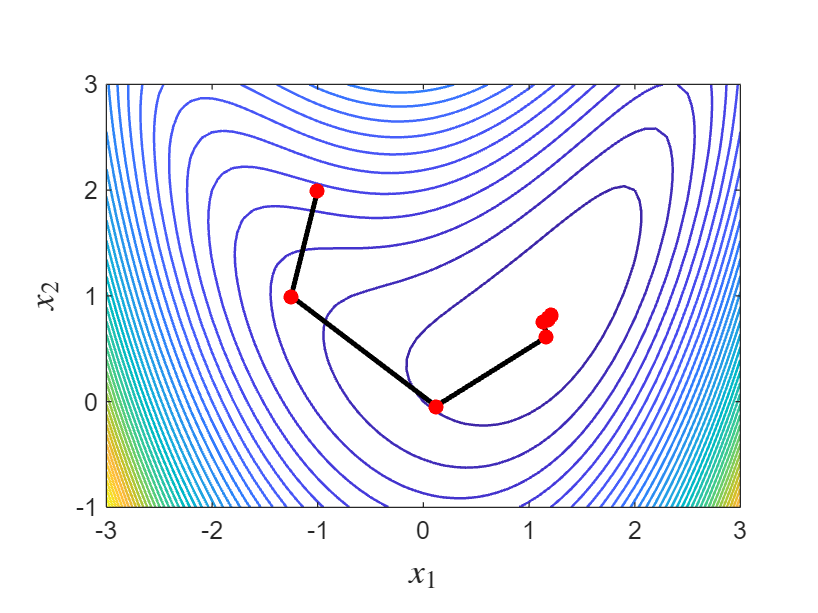


%========================================================
% Select contour plot for different funcition
[Xc,Yc] = meshgrid(xc1,xc2);
Zc = f(Xc,Yc);

if fselect
    % quadratic function
    contour(Xc,Yc,Zc, -100:40:800, 'LineWidth',1);
else
    % bean function 
    contour(Xc,Yc,Zc, -500:2:100, 'LineWidth',1);
end



xlabel("$x_1$",'Interpreter','latex',FontSize=14);
ylabel("$x_2$","FontSize",14,'Interpreter','latex')
hold on;
    plot(X(1,:), X(2,:), '-ok','linewidth', 2,...
        'MarkerFaceColor','red', 'MarkerEdgeColor','red',...
        'markersize', 4)
    axis equal
hold off;